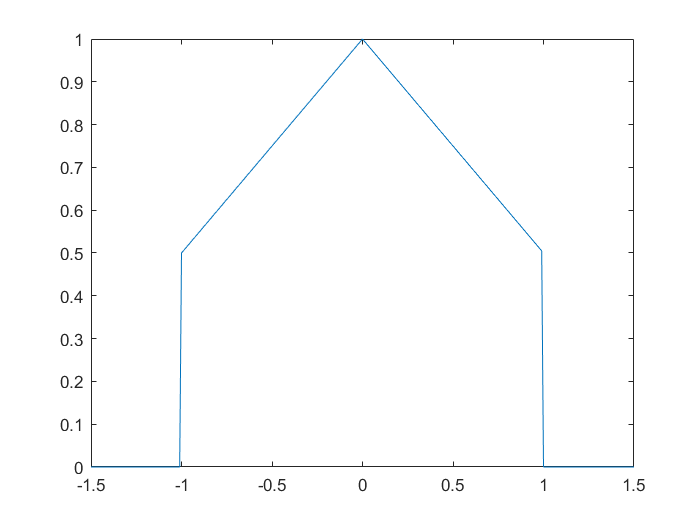

clc
clear
close all

%t=-5:0.01:-5;
%x1=(1-abs(t/2)).*rect(t,-1,1,1);
%plot(t,x1);
T=3;w0=(2*pi)/T;
f0=1;fs=100*f0;
t_vec=-T/2:(1/fs):T/2;
%x1_t=zeros(size(t_vec));
x1_t=(1-abs(t_vec/2)).*rect(t_vec,-1,1,1);
plot(t_vec,x1_t);

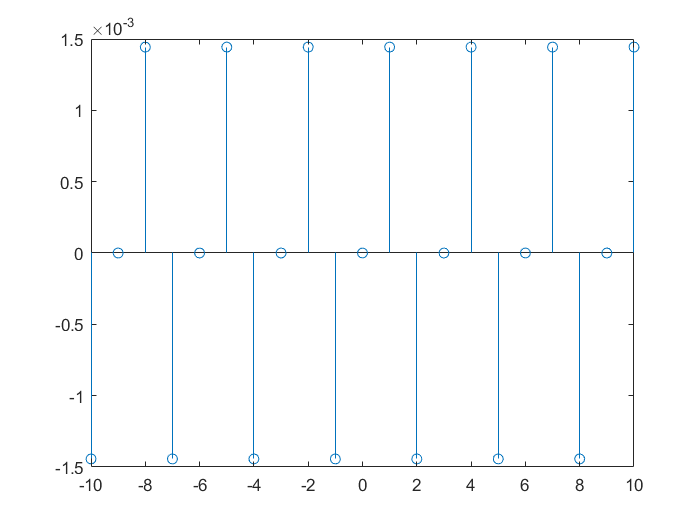

k_vec=-10:1:10; 
for l=1:length(k_vec)
    k=k_vec(l);
    %y5(l)=(1-cos(w0*k))/(k*k*w0*w0) + (sin(k*w0))/(k*w0);
    %if k_vec(l)==0
    %    y5(l)=0.5;
    %end
    basis=exp(-1i*w0*k*t_vec);
    a(l)=(1/T)*trapz(t_vec,x1_t.*basis);
end
stem(k_vec,imag(a));

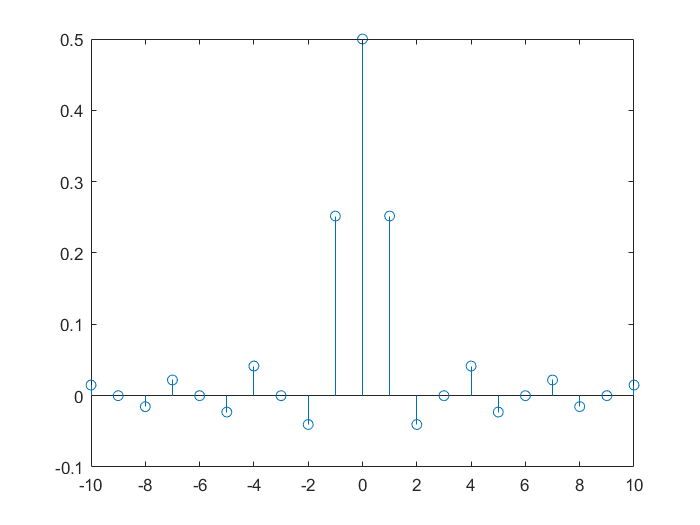

stem(k_vec,real(a));

% stem(k_vec,a);
%stem(k_vec,y5);


